% Initialize symbols 
syms M m1 m2 l1 l2 g F t1 t2 x x_ t1_ t2_;

% Setup the functions after small angle approximation 
X_dotdot =(F - m1*g*t1 - m2*g*t2)/M;
t1_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t1)/(M*l1);
t2_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t2)/(M*l2);

% Setup state and input vectors
X_states = [x x_ t1 t1_ t2 t2_];
X_eq = [x_ X_dotdot t1_ t1_dotdot t2_ t2_dotdot];
U_input = F;

% Programmatically attain A matrix through Jacobian linearization
A_ = zeros(length(X_eq), length(X_states)) + x;
for i = 1:length(X_eq)
    for j = 1:length(X_states)
        A_(i, j) = diff(X_eq(i), X_states(j));
    end
end
disp(A_)

$$\left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{g\,m_{1}}{M} & 0 & -\frac{g\,m_{2}}{M} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{M\,g+g\,m_{1}}{M\,l_{1}} & 0 & -\frac{g\,m_{2}}{M\,l_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{g\,m_{1}}{M\,l_{2}} & 0 & -\frac{M\,g+g\,m_{2}}{M\,l_{2}} & 0 \end{array}\right)$$


% Programmatically attain B matrix through Jacobian linearization
B_ = zeros(length(X_states), length(U_input)) + x;
for i = 1:length(U_input)
    for j = 1:length(X_eq)
        B_(j, i) = diff(X_eq(j), U_input(i));
    end
end
disp(B_)

$$\left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ \frac{1}{M\,l_{1}}\\ 0\\ \frac{1}{M\,l_{2}} \end{array}\right)$$


n = size(A_, 1); 

% Set Initial Condition
X0 = [0 ; 0.1 ; 10 ; 0.2 ; 5 ; 0.3];

% Set System Parameters
M_v = 1000;
m1_v = 100;
m2_v = 100;
l1_v = 20;
l2_v = 10;
g_v = 9.8;

% Substitute System Parameters into Symbolic Matrices
A = double(subs(A_, {M m1 m2 l1 l2 g}, {M_v m1_v m2_v l1_v l2_v g_v}))

A =          0    1.0000         0         0         0         0
         0         0   -0.9800         0   -0.9800         0
         0         0         0    1.0000         0         0
         0         0   -0.5390         0   -0.0490         0
         0         0         0         0         0    1.0000
         0         0   -0.0980         0   -1.0780         0


B = double(subs(B_, {M l1 l2}, {M_v l1_v l2_v}))

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000



% Setup Gain Matrices
R = 0.0001;
Q1 = 1;
Q2 = 100;
Q3 = 1;
Q4 = 100;
Q5 = 10;
Q6 = 10;

Q = diag([Q1, Q2, Q3, Q4, Q5, Q6]);

% C Matrices using Output Vectors
C_x = [1 0 0 0 0 0] 

C_x =      1     0     0     0     0     0


C_xt2 = [C_x; 0 0 0 0 1 0]

C_xt2 =      1     0     0     0     0     0
     0     0     0     0     1     0


C_xt1t2 = [C_x ; 0 0 1 0 0 0 ; 0 0 0 0 1 0]

C_xt1t2 =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0


L =     7.5000
   21.7330
   -0.6777
   18.6608
  -26.3606
  -18.7464


A_lqg =          0    1.0000         0         0         0         0         0         0         0         0         0         0
   -0.1000   -1.1165   -1.2076   -0.0670   -1.0756    0.0390    0.1000    1.1165    0.2276    0.0670    0.0956   -0.0390
         0         0         0    1.0000         0         0         0         0         0         0         0         0
   -0.0050   -0.0558   -0.5504   -0.0034   -0.0538    0.0019    0.0050    0.0558    0.0114    0.0034    0.0048   -0.0019
         0         0         0         0         0    1.0000         0         0         0         0         0         0
   -0.0100   -0.1117   -0.1208   -0.0067   -1.0876    0.0039    0.0100    0.1117    0.0228    0.0067    0.0096   -0.0039
         0         0         0         0         0         0   -7.5000    1.0000         0         0         0         0
         0         0         0         0         0         0  -21.7330         0   -0.9800         0   -0.9800         0
         0         0    

C_lqg =      1     0     0     0     0     0     0     0     0     0     0     0


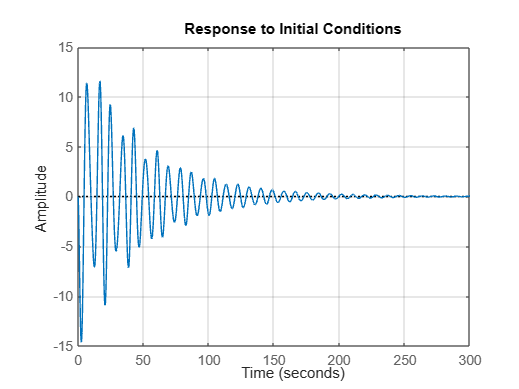

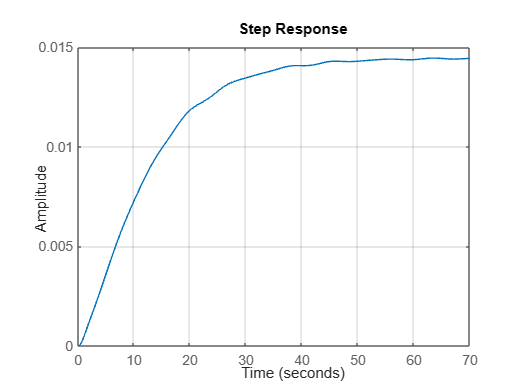

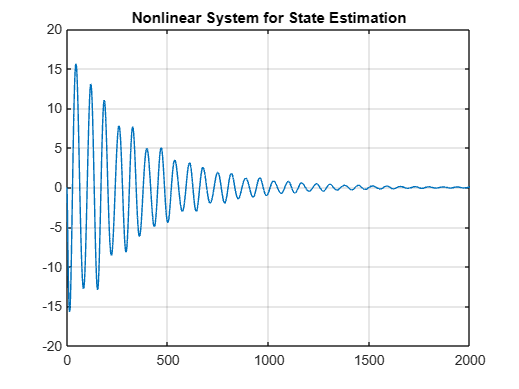

L =     5.6414   -6.5661
   11.1878  -25.7132
   -7.7682   27.7377
    2.5098   -0.8161
    0.3114    1.8586
    0.9605   -1.9845


A_lqg =          0    1.0000         0         0         0         0         0         0         0         0         0         0
   -0.1000   -1.1165   -1.2076   -0.0670   -1.0756    0.0390    0.1000    1.1165    0.2276    0.0670    0.0956   -0.0390
         0         0         0    1.0000         0         0         0         0         0         0         0         0
   -0.0050   -0.0558   -0.5504   -0.0034   -0.0538    0.0019    0.0050    0.0558    0.0114    0.0034    0.0048   -0.0019
         0         0         0         0         0    1.0000         0         0         0         0         0         0
   -0.0100   -0.1117   -0.1208   -0.0067   -1.0876    0.0039    0.0100    0.1117    0.0228    0.0067    0.0096   -0.0039
         0         0         0         0         0         0   -5.6414    1.0000         0         0    6.5661         0
         0         0         0         0         0         0  -11.1878         0   -0.9800         0   24.7332         0
         0         0    

C_lqg =      1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0


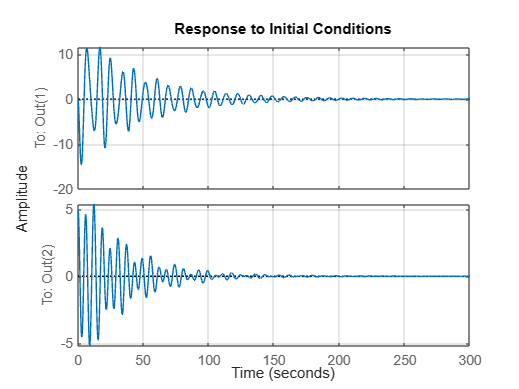

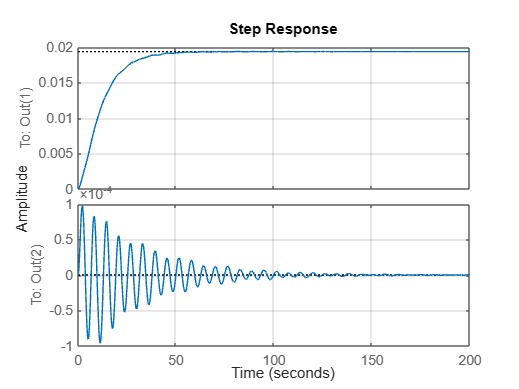

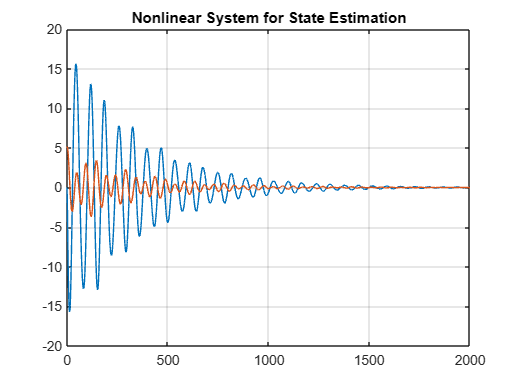

L =     2.8000    0.0008    0.0000
    1.9500   -0.9789   -0.9800
    0.0039    2.6000    0.0000
    0.0055    1.1410   -0.0490
    0.0000    0.0000    2.1000
    0.0000   -0.0980    0.0220


A_lqg =          0    1.0000         0         0         0         0         0         0         0         0         0         0
   -0.1000   -1.1165   -1.2076   -0.0670   -1.0756    0.0390    0.1000    1.1165    0.2276    0.0670    0.0956   -0.0390
         0         0         0    1.0000         0         0         0         0         0         0         0         0
   -0.0050   -0.0558   -0.5504   -0.0034   -0.0538    0.0019    0.0050    0.0558    0.0114    0.0034    0.0048   -0.0019
         0         0         0         0         0    1.0000         0         0         0         0         0         0
   -0.0100   -0.1117   -0.1208   -0.0067   -1.0876    0.0039    0.0100    0.1117    0.0228    0.0067    0.0096   -0.0039
         0         0         0         0         0         0   -2.8000    1.0000   -0.0008         0   -0.0000         0
         0         0         0         0         0         0   -1.9500         0   -0.0011         0   -0.0000         0
         0         0    

C_lqg =      1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0


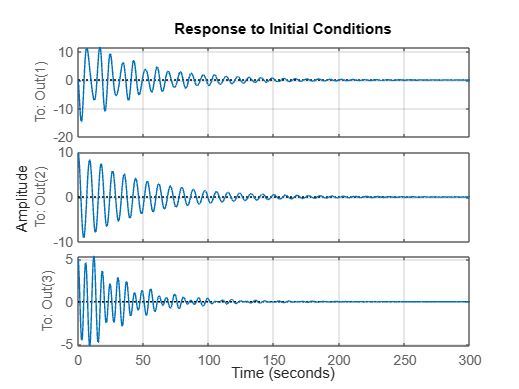

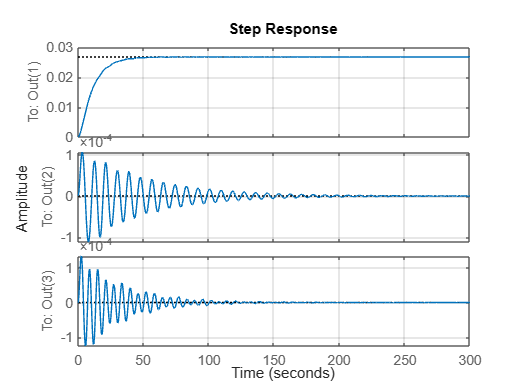

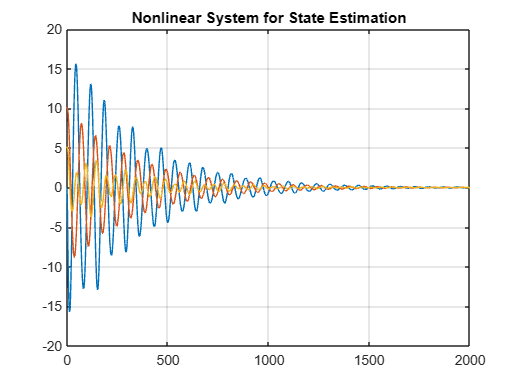


C_obs = {C_x C_xt2 C_xt1t2};


D = 0;

% Find LQR Gain Matrix
[K, P_lqr, poles_lqr] = lqr(A, B, Q, R);

% Poles for Luenberger Observation Gain Matrix
poles = [-1; -1.1; -1.2; -1.3; -1.4; -1.5];

for i=1:size(C_obs, 2)
    C_using = C_obs{i};

    % Setup Luenberger Gain Matrix
    L = place(A', C_using', poles)'
    
    % Setup State Estimation Matrices A, B, C
    A_lqg = [A-(B*K) B*K; zeros(n,n) A-(L*C_using)]
    B_lqg = [B; B];
    C_lqg = [ C_using zeros(size(C_using))]
    
    % Create State Space Equation for LQG
    lqg_system_behaviour = ss(A_lqg, B_lqg, C_lqg, D);
    figure;

    % Simulate LQG with Linearized Initial Condition
    initial(lqg_system_behaviour, [X0; zeros(n, 1)])
    grid on
   
    % Simulate LQG with Linearized Step Input
    figure;
    step(lqg_system_behaviour)
    grid on
    
    % Nonlinear System Simulation
    time_period = 0:0.01:2000 ;
    [t,X] = ode45(@(t,X) nonlinearfeedback(t, X, K, L, A, C_using, M_v, m1_v, m2_v, l1_v, l2_v, g_v),time_period,[X0; zeros(n, 1)]);
    figure;
    if size(C_using, 1) == 1
        plot(t,X(:, 1))
    elseif size(C_using, 1) == 2
        plot(t,X(:, 1))
        hold on
        plot(t,X(:, 5))
    elseif size(C_using, 1) == 3
        plot(t,X(:, 1))
        hold on
        plot(t,X(:, 3))
        hold on
        plot(t,X(:, 5))
    end
    title('Nonlinear System for State Estimation');
    grid on
end

function y_dot = nonlinearfeedback(t, X, K, L, A, C, M, m1, m2, l1, l2, g)
F = -K*X(1:6) ;
X_hat = (A-(L*C))*X(7:12);
y_dot = zeros(12,1) ;
y_dot(1,1) = X(2) ;
y_dot(2,1) = (1/(M+m1+m2))*(F+(m1*l1*y_dot(4,1)*cosd(X(3)))+(m2*l2*y_dot(6,1)*cosd(X(5)))-(m1*l1*(X(4)^2)*sind(X(3)))-(m2*l2*(X(6)^2)*sind(X(5))));
y_dot(3,1) = X(4) ;
y_dot(4,1) = (y_dot(2,1)*cosd(X(3))-g*(sind(X(3))))/l1 ;
y_dot(5,1) = X(6) ;
y_dot(6,1) = (y_dot(2,1)*cosd(X(5))-g*(sind(X(5))))/l2 ;
y_dot(7,1) = y_dot(1,1) + X_hat(1);
y_dot(8,1) = y_dot(2,1) + X_hat(2);
y_dot(9,1) = y_dot(3,1) + X_hat(3);
y_dot(10,1) = y_dot(4,1) + X_hat(4);
y_dot(11,1) = y_dot(5,1) + X_hat(5);
y_dot(12,1) = y_dot(6,1) + X_hat(6);
end
